syms b k M s 

A=[-b/M -k/M;1 0];
B=[1/M ;0];
C=[0 1];
D=0;

Phi=inv(s*eye(2)-A)

$$Phi = \left(\begin{array}{cc} \frac{M\,s}{M\,s^{2}+b\,s+k} & -\frac{k}{M\,s^{2}+b\,s+k}\\ \frac{M}{M\,s^{2}+b\,s+k} & \frac{b+M\,s}{M\,s^{2}+b\,s+k} \end{array}\right)$$

G=C*Phi*B+D

$$G = \frac{1}{M\,s^{2}+b\,s+k}$$

[n ,d]=numden(G)

$$n = 1$$

$$d = M\,s^{2}+b\,s+k$$

num=flip(coeffs(n,s))

$$num = 1$$

den=flip(coeffs(d,s))

$$den = \left(\begin{array}{ccc} M & b & k \end{array}\right)$$


[A ,B, C, D]=tf2ss(num,den)

$$A = \left(\begin{array}{cc} -\frac{b}{M} & -\frac{k}{M}\\ 1 & 0 \end{array}\right)$$

$$B = \left(\begin{array}{c} 1\\ 0 \end{array}\right)$$

$$C = \left(\begin{array}{cc} 0 & \frac{1}{M} \end{array}\right)$$

$$D = 0$$

num=[ 0 0 1 2];
den=[1 5 -24 0 ];
[A B C D]=tf2ss(num,den)

A =     -5    24     0
     1     0     0
     0     1     0


B =      1
     0
     0


C =      0     1     2


D = 0

syms s

A=[-12 -44 -48;1 0 0;0 1 0];
Phi=s*eye(3)-A 

$$Phi = \left(\begin{array}{ccc} s+12 & 44 & 48\\ -1 & s & 0\\ 0 & -1 & s \end{array}\right)$$

inv(Phi)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} \frac{s^{2}}{\sigma_{1}} & -\frac{4\,\left(11\,s+12\right)}{\sigma_{1}} & -\frac{48\,s}{\sigma_{1}}\\ \frac{s}{\sigma_{1}} & \frac{s\,\left(s+12\right)}{\sigma_{1}} & -\frac{48}{\sigma_{1}}\\ \frac{1}{\sigma_{1}} & \frac{s+12}{\sigma_{1}} & \frac{s^{2}+12\,s+44}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=s^{3}+12\,s^{2}+44\,s+48 \end{array}$$

phi_t=ilaplace(inv(Phi))

$$phi\_t = \begin{array}{l} \left(\begin{array}{ccc} \frac{{\mathrm{e}}^{-2\,t}}{2}-4\,{\mathrm{e}}^{-4\,t}+\sigma_{2} & \sigma_{1}-32\,{\mathrm{e}}^{-4\,t}+27\,{\mathrm{e}}^{-6\,t} & 12\,{\mathrm{e}}^{-2\,t}-48\,{\mathrm{e}}^{-4\,t}+36\,{\mathrm{e}}^{-6\,t}\\ {\mathrm{e}}^{-4\,t}-\frac{{\mathrm{e}}^{-2\,t}}{4}-\sigma_{3} & 8\,{\mathrm{e}}^{-4\,t}-\frac{\sigma_{1}}{2}-\sigma_{2} & 12\,{\mathrm{e}}^{-4\,t}-6\,{\mathrm{e}}^{-2\,t}-6\,{\mathrm{e}}^{-6\,t}\\ \frac{{\mathrm{e}}^{-2\,t}}{8}-\frac{{\mathrm{e}}^{-4\,t}}{4}+\frac{{\mathrm{e}}^{-6\,t}}{8} & \frac{\sigma_{1}}{4}-2\,{\mathrm{e}}^{-4\,t}+\sigma_{3} & 3\,{\mathrm{e}}^{-2\,t}-3\,{\mathrm{e}}^{-4\,t}+{\mathrm{e}}^{-6\,t} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=5\,{\mathrm{e}}^{-2\,t}\\ \sigma_{2}=\frac{9\,{\mathrm{e}}^{-6\,t}}{2}\\ \sigma_{3}=\frac{3\,{\mathrm{e}}^{-6\,t}}{4} \end{array}$$

syms s
A=[1 1 -1;4 3 0;-2 1 10];
B=[0;0;4];
C=[1 0 0];
D=0;

Phi_s=inv(s*eye(3)-A)

$$Phi\_s = \begin{array}{l} \left(\begin{array}{ccc} \frac{\left(s-3\right)\,\left(s-10\right)}{\sigma_{1}} & \frac{s-11}{\sigma_{1}} & -\frac{s-3}{\sigma_{1}}\\ \frac{4\,\left(s-10\right)}{\sigma_{1}} & \frac{s^{2}-11\,s+8}{\sigma_{1}} & -\frac{4}{\sigma_{1}}\\ -\frac{2\,\left(s-5\right)}{\sigma_{1}} & \frac{s-3}{\sigma_{1}} & -\frac{-s^{2}+4\,s+1}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=s^{3}-14\,s^{2}+37\,s+20 \end{array}$$

G=C*Phi_s*B

$$G = -\frac{4\,\left(s-3\right)}{s^{3}-14\,s^{2}+37\,s+20}$$

n=-10:1:10;

x2n=stepfun(n,-3);
x3n=(stepfun(n,0)-stepfun(n,1))-(stepfun(n,1)-stepfun(n,2))

x3n =      0     0     0     0     0     0     0     0     0     0     1    -1     0     0     0     0     0     0     0     0     0


syms s t tau;

A=[0 -2;1 -3];
B=[2;0];
C=[0 3];
D=0;

Phi(s)=inv((s*eye(2)-A));
Phi_t=ilaplace(Phi(s));
Phi_tau=subs(Phi(t),t,t-tau);
x_0 =[0;0];
x=Phi_t*x_0 + int(Phi_tau*B, tau,[0,t])

$$x = \begin{array}{l} \left(\begin{array}{c} 12\,\mathrm{atanh}\left(3\right)-12\,\sigma_{1}-2\,\left(\log\left(2\right)+\pi \,\mathrm{i}\right)\,\left(t+2\right)-2\,\log\left(-t-1\right)\,\left(t+1\right)+2\,\log\left(-t-2\right)\,\left(t+2\right)+2\,t\,\left(2\,\mathrm{atanh}\left(3\right)-2\,\sigma_{1}\right)+2\,\pi \,\left(t+1\right)\,\mathrm{i}\\ 4\,\mathrm{atanh}\left(3\right)-4\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{atanh}\left(2\,t+3\right) \end{array}$$

y=C*x

$$y = 12\,\mathrm{atanh}\left(3\right)-12\,\mathrm{atanh}\left(2\,t+3\right)$$

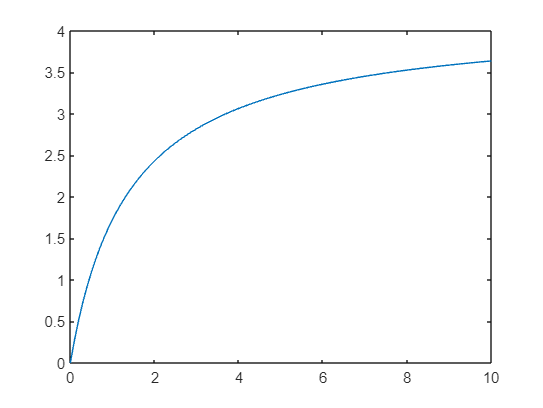

t_=0:0.1:10;
plot(t_,subs(y,t,t_))